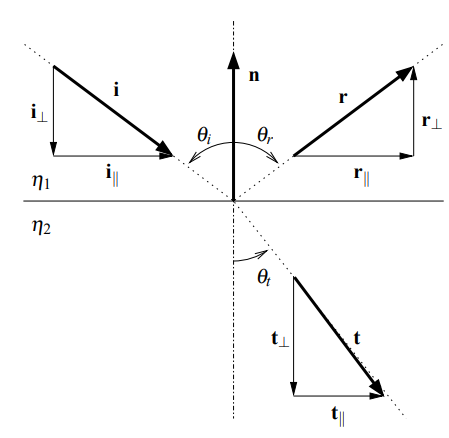$\text{Function calculates transmitted vector - t, given incoming vector - i, 

surface normal - n and  materials refractive indices \eta i  and \eta t } \\

\vec{t} = \frac{\eta_i}{\eta_t}\textbf{i} + \Big( \frac{\eta_i}{\eta_t}  \cos \theta_i -\sqrt{1-\sin^2\theta_t} \Big) \textbf n \\@
\cos \theta_i \equiv - \textbf {i \bullet n},\, \sin^2\theta_t \equiv \Big(  \frac{\eta_i}{\eta_t}  \Big)^2(1-\cos^2\theta_i)$

function t = refraction_func(i, n, eta_i, eta_t)
i = i/norm(i);
n = n/norm(n);

cos_theta_i = -dot(i, n);
er = eta_i/eta_t;

t = (er)*i + (er*cos_theta_i - sqrt(1-(er^2*(1-cos_theta_i^2))))*n;
end